clc,clear,close all
syms x
syms newFunction(x) newFuncPrime(x)

%------Finding Functions-------------
mainFunctions=sym([1,8]);
mainFunctions(1,1)=sinh(x)/x;

for i=2:8
    sigmaFunc=0;
    for j=0:i+2
        sigmaFunc= sigmaFunc+((x^(2*j))/factorial(2*j+1));
    end
    mainFunctions(1,i)=sigmaFunc;
end

mainFunctions

$$mainFunctions = \left(\begin{array}{cccccccc} \frac{\sinh\left(x\right)}{x} & \frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 & \frac{x^{10}}{39916800}+\frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 & \frac{x^{12}}{6227020800}+\frac{x^{10}}{39916800}+\frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 & \frac{x^{14}}{1307674368000}+\frac{x^{12}}{6227020800}+\frac{x^{10}}{39916800}+\frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 & \frac{x^{16}}{355687428096000}+\frac{x^{14}}{1307674368000}+\frac{x^{12}}{6227020800}+\frac{x^{10}}{39916800}+\frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 & \frac{x^{18}}{121645100408832000}+\frac{x^{16}}{355687428096000}+\frac{x^{14}}{1307674368000}+\frac{x^{12}}{6227020800}+\frac{x^{10}}{39916800}+\frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 & \frac{x^{20}}{51090942171709440000}+\frac{x^{18}}{121645100408832000}+\frac{x^{16}}{355687428096000}+\frac{x^{14}}{1307674368000}+\frac{x^{12}}{6227020800}+\frac{x^{10}}{39916800}+\frac{x^{8}}{362880}+\frac{x^{6}}{5040}+\frac{x^{4}}{120}+\frac{x^{2}}{6}+1 \end{array}\right)$$

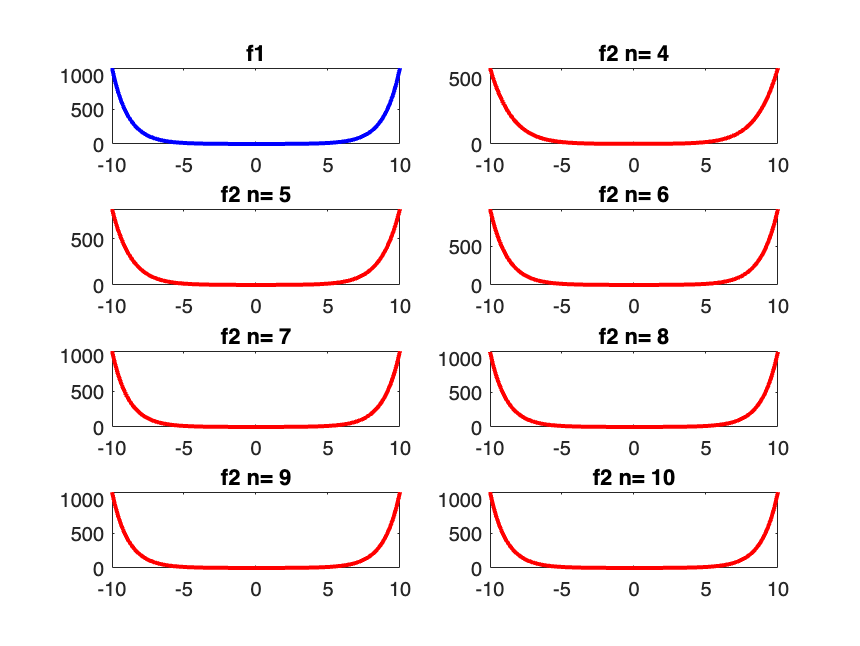


%---------Part A - Ploting ------------
range=10;

f1=figure;
subplot(4,2,1);
fplot(mainFunctions(1,1),[-range,range],'b','LineWidth',2);
title('f1');

for i=2:8
    subplot(4,2,i);
    fplot(mainFunctions(1,i),[-range,range],'r','LineWidth',2);
    title(['f2 n= ',num2str(i+2)]);
end

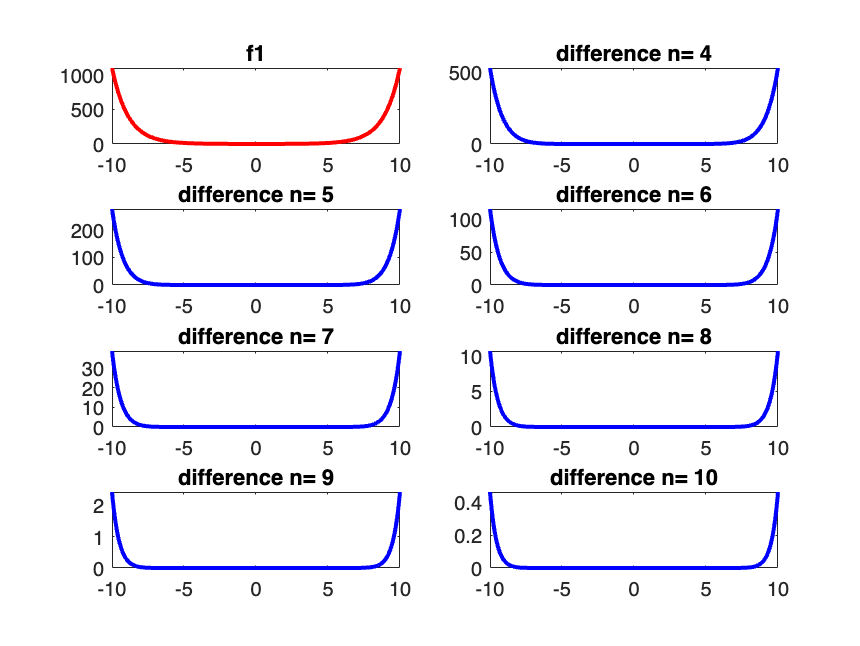


f2 =figure;
subplot(4,2,1);
fplot(mainFunctions(1,1),[-range,range],'r','LineWidth',2);
title('f1');

for i=2:8
    subplot(4,2,i);
    minus= mainFunctions(1,1)-mainFunctions(1,i);
    fplot(minus,[-range,range],'b','LineWidth',2);
    title(['difference n= ',num2str(i+2)]);
end


%------------Part B - Limits------------
functionsLimit= zeros(1,8);
for i= 1:8
    functionsLimit(1,i)=limit(mainFunctions(1,i),x,0);
end

functionsLimit

functionsLimit =      1     1     1     1     1     1     1     1



%-------------Part D - Newton Method--------
n=4;
error = 10^(-5); 
newFunction(x)= mainFunctions(1,1)-mainFunctions(1,n-2)

$$newFunction(x) = \frac{\sinh\left(x\right)}{x}-\frac{x^{2}}{6}-\frac{x^{4}}{120}-\frac{x^{6}}{5040}-\frac{x^{8}}{362880}-1$$

newFuncPrime(x)= diff(newFunction,x)

$$newFuncPrime(x) = \frac{\cosh\left(x\right)}{x}-\frac{x}{3}-\frac{\sinh\left(x\right)}{x^{2}}-\frac{x^{3}}{30}-\frac{x^{5}}{840}-\frac{x^{7}}{45360}$$


result=10;

while abs(vpa(newFunction(result))) > error
    result= result-vpa(newFunction(result)/newFuncPrime(result),abs(log(error)/log(10))+1);
end

result = vpa(result,abs(log(error)/log(10))+1)

$$result = 1.81509$$